## Spectrogram Generation 

### Control Signals

% Locate the TVALID and TLAST control signals of the FFT
fft_out_tvalid = out.TVALID

fft_out_tvalid =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


find(fft_out_tvalid == 1, 1)

ans = 4237

fft_out_tlast = out.TLAST

fft_out_tlast =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


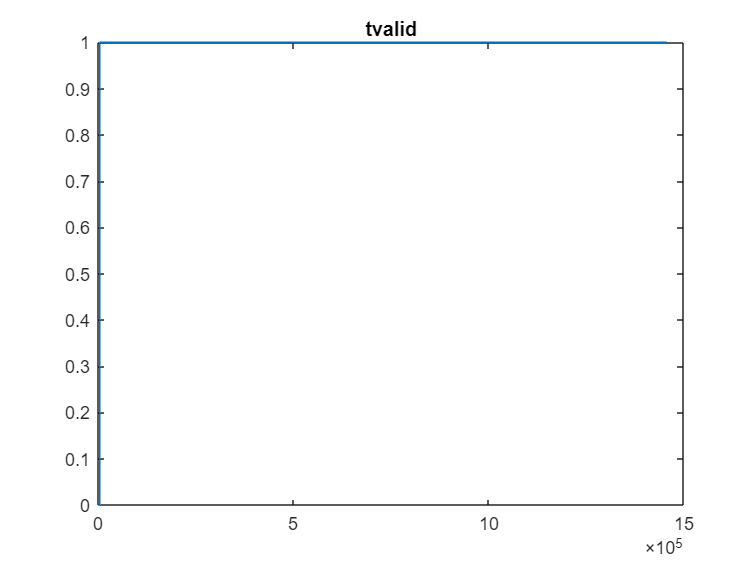

plot(1:length(fft_out_tvalid),fft_out_tvalid)
title('tvalid')

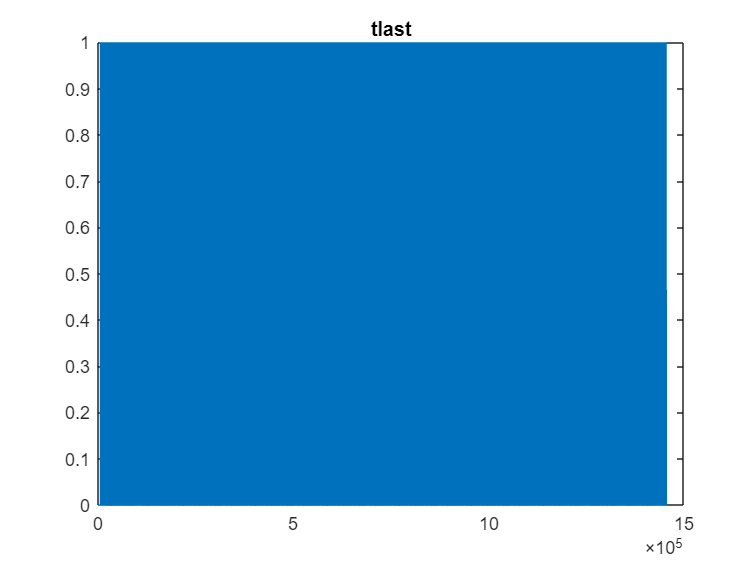

plot(1:length(fft_out_tlast),fft_out_tlast)
title('tlast')


% Set TLAST signal from first TVALID to keep it with data output
fft_out_tlast = fft_out_tlast(find(fft_out_tvalid == 1, 1):end)

fft_out_tlast =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


find(fft_out_tlast,1,'first')

ans = 2048


% Locate the FFT data output
fft_out_log_ = out.FFT_out_log

fft_out_log_ =      0
     0
     0
     0
   -64
   -64
   -64
   -64
   -64
   -64


% Only keep the valid samples
fft_out_log = fft_out_log_(find(fft_out_tvalid == 1, 1):end)

fft_out_log =    -64
   -64
   -64
   -64
   -64
   -64
   -64
   -64
   -64
   -64


% Zero-pad if neccessary to ensure # samples is an integer multiple of the
% window size (required for easier spectrogram plotting)
fft_length_before_zero_padding = (ceil(length(fft_out_log)/N))

fft_length_before_zero_padding = 709


% Set the zero-padded values to the minimum value of the valid samples
fft_out_log(length(fft_out_log)+1:fft_length_before_zero_padding*N)=min(fft_out_log)

fft_out_log =    -64
   -64
   -64
   -64
   -64
   -64
   -64
   -64
   -64
   -64


### HDL block floating point 

% Determine key parameters
Total_Num_Samples = length(fft_out_log)

Total_Num_Samples = 1452032

Num_Segments = Total_Num_Samples/N

Num_Segments = 709


% Create the frequency and time axis for both spectrograms
f_axis_1N = (n/N*fs)/1e6; % From 0 -> fs
f_axis_1N_ = (-N/2:N/2-1)*(fs/N)/1e6; % From -fs/2 -> fs/2 (combined with fftshift for centring DC - as high f is just a spectral replication of -ve f)
t_axis_1N = linspace(0,Total_Num_Samples/fs,Num_Segments)

t_axis_1N =          0    0.0001    0.0003    0.0004    0.0005    0.0006    0.0008    0.0009    0.0010    0.0012    0.0013    0.0014    0.0015    0.0017    0.0018    0.0019    0.0021    0.0022    0.0023    0.0024    0.0026    0.0027    0.0028    0.0029    0.0031    0.0032    0.0033    0.0035    0.0036    0.0037    0.0038    0.0040    0.0041    0.0042    0.0044    0.0045    0.0046    0.0047    0.0049    0.0050    0.0051    0.0053    0.0054    0.0055    0.0056    0.0058    0.0059    0.0060    0.0062    0.0063


t_axis_1N = 1e3.*t_axis_1N

t_axis_1N =          0    0.1282    0.2564    0.3845    0.5127    0.6409    0.7691    0.8973    1.0254    1.1536    1.2818    1.4100    1.5382    1.6664    1.7945    1.9227    2.0509    2.1791    2.3073    2.4354    2.5636    2.6918    2.8200    2.9482    3.0763    3.2045    3.3327    3.4609    3.5891    3.7172    3.8454    3.9736    4.1018    4.2300    4.3581    4.4863    4.6145    4.7427    4.8709    4.9991    5.1272    5.2554    5.3836    5.5118    5.6400    5.7681    5.8963    6.0245    6.1527    6.2809


f_axis = repmat(f_axis_1N,1,Num_Segments)

f_axis =          0    0.0078    0.0156    0.0234    0.0312    0.0391    0.0469    0.0547    0.0625    0.0703    0.0781    0.0859    0.0938    0.1016    0.1094    0.1172    0.1250    0.1328    0.1406    0.1484    0.1562    0.1641    0.1719    0.1797    0.1875    0.1953    0.2031    0.2109    0.2188    0.2266    0.2344    0.2422    0.2500    0.2578    0.2656    0.2734    0.2812    0.2891    0.2969    0.3047    0.3125    0.3203    0.3281    0.3359    0.3438    0.3516    0.3594    0.3672    0.3750    0.3828


f_axis_ = repmat(f_axis_1N_,1,Num_Segments)

f_axis_ =    -8.0000   -7.9922   -7.9844   -7.9766   -7.9688   -7.9609   -7.9531   -7.9453   -7.9375   -7.9297   -7.9219   -7.9141   -7.9062   -7.8984   -7.8906   -7.8828   -7.8750   -7.8672   -7.8594   -7.8516   -7.8438   -7.8359   -7.8281   -7.8203   -7.8125   -7.8047   -7.7969   -7.7891   -7.7812   -7.7734   -7.7656   -7.7578   -7.7500   -7.7422   -7.7344   -7.7266   -7.7188   -7.7109   -7.7031   -7.6953   -7.6875   -7.6797   -7.6719   -7.6641   -7.6562   -7.6484   -7.6406   -7.6328   -7.6250   -7.6172


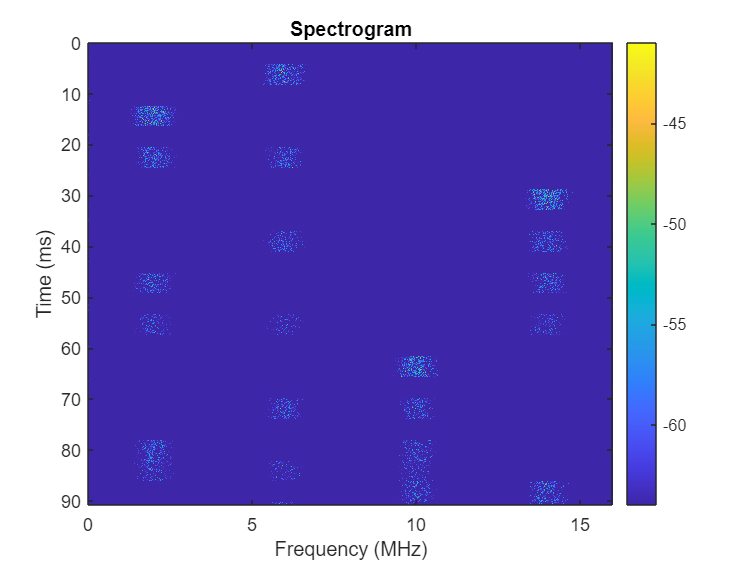


% Fill in the arrays to plot the spectrograms
for i=1:Num_Segments
    index = (i-1)*N+1 : i*N;
    t_axis(index) = t_axis_1N(i);   
    Data(i,:) = fft_out_log(index);
    Data_shift(i,:) = fftshift(Data(i,:));
end

% Plot spectrograms 
figure;
imagesc(f_axis,t_axis,Data)
title('Spectrogram')
xlabel('Frequency (MHz)')
ylabel('Time (ms)')
colorbar

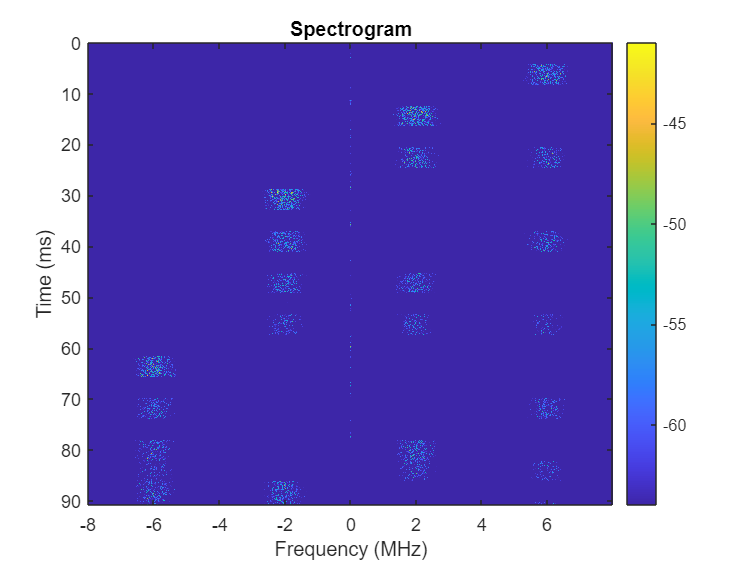

figure;
imagesc(f_axis_,t_axis,Data_shift)
title('Spectrogram')
xlabel('Frequency (MHz)')
ylabel('Time (ms)')
colorbar

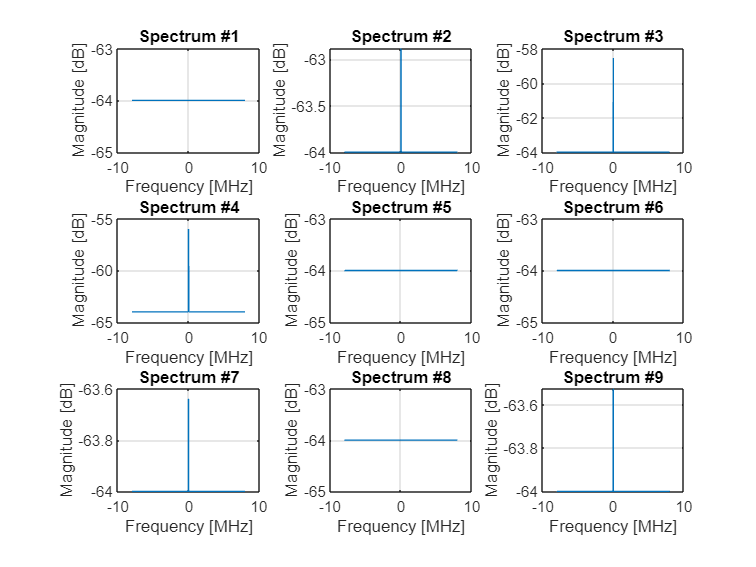

spectrum =    -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64


spectrum =    -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64


spectrum =    -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64


spectrum =    -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64


spectrum =    -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64


spectrum =    -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64


spectrum =    -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64


spectrum =    -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64


spectrum =    -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64   -64


figure;
for idx = 1:9
    % Plot idx spectrum 
    subplot(3,3,idx);
    spectrum = Data_shift(idx,:)
    plot(f_axis_1N_,spectrum);
    xlabel('Frequency [MHz]');
    ylabel('Magnitude [dB]');
    title(sprintf('Spectrum #%s',num2str(idx)));
    grid on;
end